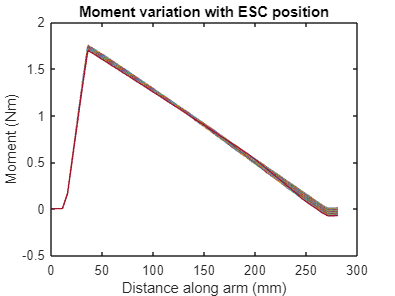

clear 
clc

E = 17000000000;
SigmaMax = 36000000;
SafetyFactor = 2;
Sigma = SigmaMax/SafetyFactor;
density = 1.1;


MaxMotorThrust = 800; %grams
ESCMass = 40; %grams
ESCLength = 50; %mm

FMotorMax = MaxMotorThrust*9.81/1000;
% ESCDistLoad = (ESCMass*9.81/1000)/(ESCLength/1000);

a = 40:5:175; % Placement of ESC (mm from centre of mounting points)
FN2 = (FMotorMax*0.261 - 2*0.285*0.1335 - 8.*0.05.*(a+36)./1000)./0.022; % Force at support 2 from moments
FN1 = FN2 - FMotorMax + 2*0.285 + 8*0.05; % Force at support 1 from force balance

x = 1:5:285; % set sample locations along beam for measurements

% Moment Calculations
M = zeros(length(FN1), length(x));

for j = 1:length(a)
    for i = 1:length(x)
        if x(i) <= 9
            M(j,i+1) = -2*(x(i)/1000)*(x(i)/2000);
        elseif x(i) <= 31
            M(j,i+1) = FN1(j).*(x(i)-9)./1000 - 2*(x(i)/1000)*(x(i)/2000);
        elseif x(i) <= a(j)+20
            M(j,i) = FN1(j).*(x(i)-9)./1000 - FN2(j).*(x(i)-31)./1000 - 2*(x(i)/1000)*(x(i)/2000);
        elseif x(i) <= a(j)+70
            M(j,i) = FN1(j).*(x(i)-9)./1000 - FN2(j).*(x(i)-31)./1000 - 2*(x(i)/1000)*(x(i)/2000) - 8.*((x(i)-(a(j)+20))./1000).*((x(i)+(a(j)+20))./2000);
        elseif x(i) <= 270
            M(j,i) = FN1(j).*(x(i)-9)./1000 - FN2(j).*(x(i)-31)./1000 - 2*(x(i)/1000)*(x(i)/2000) - 8.*0.05.*((x(i)+(a(j)+45))./2000);
        else
            M(j,i) = FN1(j).*(x(i)-9)./1000 - FN2(j).*(x(i)-31)./1000 - 2*(x(i)/1000)*(x(i)/2000) - 8.*0.05.*((x(i)+(a(j)+45))./2000) + 8*(x(i)-270)./1000;
        end
    end 
end 

% Effect of ESC Position
figure()
for i = 1:length(a)
    plot(x, M(i,:))
    hold on
    xlabel('Distance along arm (mm)')
    ylabel('Moment (Nm)')
    title('Moment variation with ESC position')
end

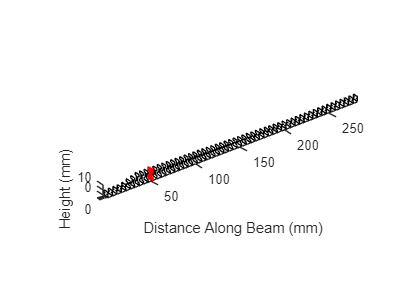

FN2 =    88.2651   88.1742   88.0833   87.9924   87.9015   87.8106   87.7197   87.6288   87.5379   87.4470   87.3560   87.2651   87.1742   87.0833   86.9924   86.9015   86.8106   86.7197   86.6288   86.5379   86.4470   86.3560   86.2651   86.1742   86.0833   85.9924   85.9015   85.8106



% Moment we will use for further calculations given the similarity of the
% above solutions for variable a
Mx = abs(M(10,:));
My = 0.50;

for i = 1:length(x)
    % Sample Point (distance from start of beam);
    MSample = Mx(i);

    % Initialise Tracking Parameters
    CSAMin = 1000;
    Opt = [0,0,0,0];

    % Sweep through different height combinations for the I beam sections
    for H1 = [0:0.1:50]
        H = H1/1000;
        for h1 = 2.5:0.1:50
            h = h1/1000;
            y = H/2 + h;
            IxxReq = MSample.*y./Sigma;

            % Sweep through different base width for the I beam sections
            for B1 = 3:0.1:50
                B = B1/1000;

                % Ensure that b is chosen to give the desired safety factor
                b = (IxxReq - 2.*((h.^3.*B)./12 + (h.*B.*(H+h).^2)./4)).*(12./(H.^3));

                % Ensure b is large enough to be physically printed
                if b < 0.0016
                    b = 0.0016;
                end
                % Find the Cross sectional area which is proportional to
                % the amount of material needed to print this part
                CSA = 2*B*h + H*b;

                if CSA < CSAMin
                    % Check the part also withstands required torsion
                    Iyy = (b^3*H/12) + 2*(B^3*h/12);
                    SigmaY = My*(B/2)/Iyy;

                    % If all conditions satisfied and this section will use
                    % less material than the previous optimal section, save
                    % parameters here
                    if SigmaY < Sigma & B > b
                        CSAMin = CSA;
                        Opt = [H,h,B,b];
                    end
                end
            end
        end
    end
    % Create an array of the optimal values
    CSAMinArray(i) = CSAMin*1000000;
    OptArray(i,:) = Opt.*1000;
end 



row = 1;

% Create a plot with the I beam sections
figure()
for i = 1:length(x)
    SectionX = [OptArray(i,3)./2, OptArray(i,3)./2, OptArray(i,4)./2, OptArray(i,4)./2, OptArray(i,3)./2, OptArray(i,3)./2, -OptArray(i,3)./2, -OptArray(i,3)./2, -OptArray(i,4)./2, -OptArray(i,4)./2, -OptArray(i,3)./2, -OptArray(i,3)./2, OptArray(i,3)./2];
    SectionY = [0, OptArray(i,2), OptArray(i,2), OptArray(i,2)+OptArray(i,1), OptArray(i,2)+OptArray(i,1), 2*OptArray(i,2)+OptArray(i,1), 2*OptArray(i,2)+OptArray(i,1), OptArray(i,2)+OptArray(i,1), OptArray(i,2)+OptArray(i,1), OptArray(i,2), OptArray(i,2), 0, 0];
    %SectionY = SectionY - (OptArray(i,1)/2 + OptArray(i,2));
    SectionZ = [x(i),x(i),x(i),x(i),x(i),x(i),x(i),x(i),x(i),x(i),x(i),x(i),x(i)];
    if i == round(length(x)/5)
        plot3(SectionZ, SectionX, SectionY, 'r', LineWidth=2)
    else
        plot3(SectionZ, SectionX, SectionY, 'k')
    end
    hold on

    % Store the points for each section in a cell array
    for j = 1:length(SectionX)
        FusionArray{row, 1} = SectionX(j);
        FusionArray{row, 2} = SectionY(j);
        FusionArray{row, 3} = SectionZ(j);
        row = row + 1;
    end 

    % Insert a blank row between each section for CAD software
    FusionArray{row, 1} = '';
    FusionArray{row, 2} = '';
    FusionArray{row, 3} = '';
    row = row + 1; 
end 
% Export optimal sectoins as a CSV file to use in Fusion 360
writecell(FusionArray, 'Fusion.csv')

axis equal
% xlim([-25,25])
% ylim([-25,25])
xlabel('Distance Along Beam (mm)')
ylabel('Width (mm)')
zlabel('Height (mm)')